display("File To Explore height diferences")

    "File To Explore height diferences"



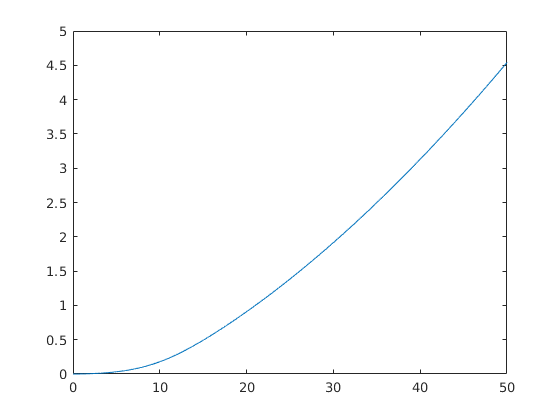

f = [0:0.01:50];
plot(f, abs(group_velocity(f)))

function v = group_velocity(freq)
    a = earthRadius;
    k = freq/physconst('LightSpeed');
    c_v = 1.64 - 0.1759 * log(freq) + 0.01791 * log(freq).^2;
    n_f = 0.063 * freq.^0.64;
    S = c_v - 1j*5.49 * n_f;
    v = sqrt((0.25 + (k .* a .* S).^2)) - 0.5;
end


